% Test of LBGAlgorithm
% INPUTS FOR FUNCTION - Number of centroids; dimension; eplison; frames
numCentroids = 4; % for test defining number of centroids
randomPoints = randi([0 10],2,10) % random data set

randomPoints =     10     0     2     6     4     3     7     7     1    10
    10     8     4    10    10     7     5     7     1     1


scatter(randomPoints(1,:),randomPoints(2,:),'b','o') % plotting random points
hold on
randomXY = randomPoints' % putting random points in [X Y] format

randomXY =     10    10
     0     8
     2     4
     6    10
     4    10
     3     7
     7     5
     7     7
     1     1
    10     1


lengthsplitup = ceil(10/numCentroids); % how to evenly split input data;frames/numC
startCentroids = zeros(numCentroids,2); % zeros(numCentroids,dimensions)
j = 0;
% for loop to give us all the initial centroids we need
for i = 1:numCentroids
    if i == 1
        startCentroids(i,:) = mean(randomXY(i:lengthsplitup,:));
    elseif i ~= numCentroids
        startCentroids(i,:) = mean(randomXY(j:j+lengthsplitup-1,:));
    else
        startCentroids(i,:) = mean(randomXY(j:end,:));
    end
    j = i + lengthsplitup; % iterating j to make sure we mean all data with no repeats
end
startCentroids % displaying initial centroid values for testing purposes

startCentroids =     4.0000    7.3333
    4.3333    9.0000
    4.6667    7.3333
    5.6000    4.2000


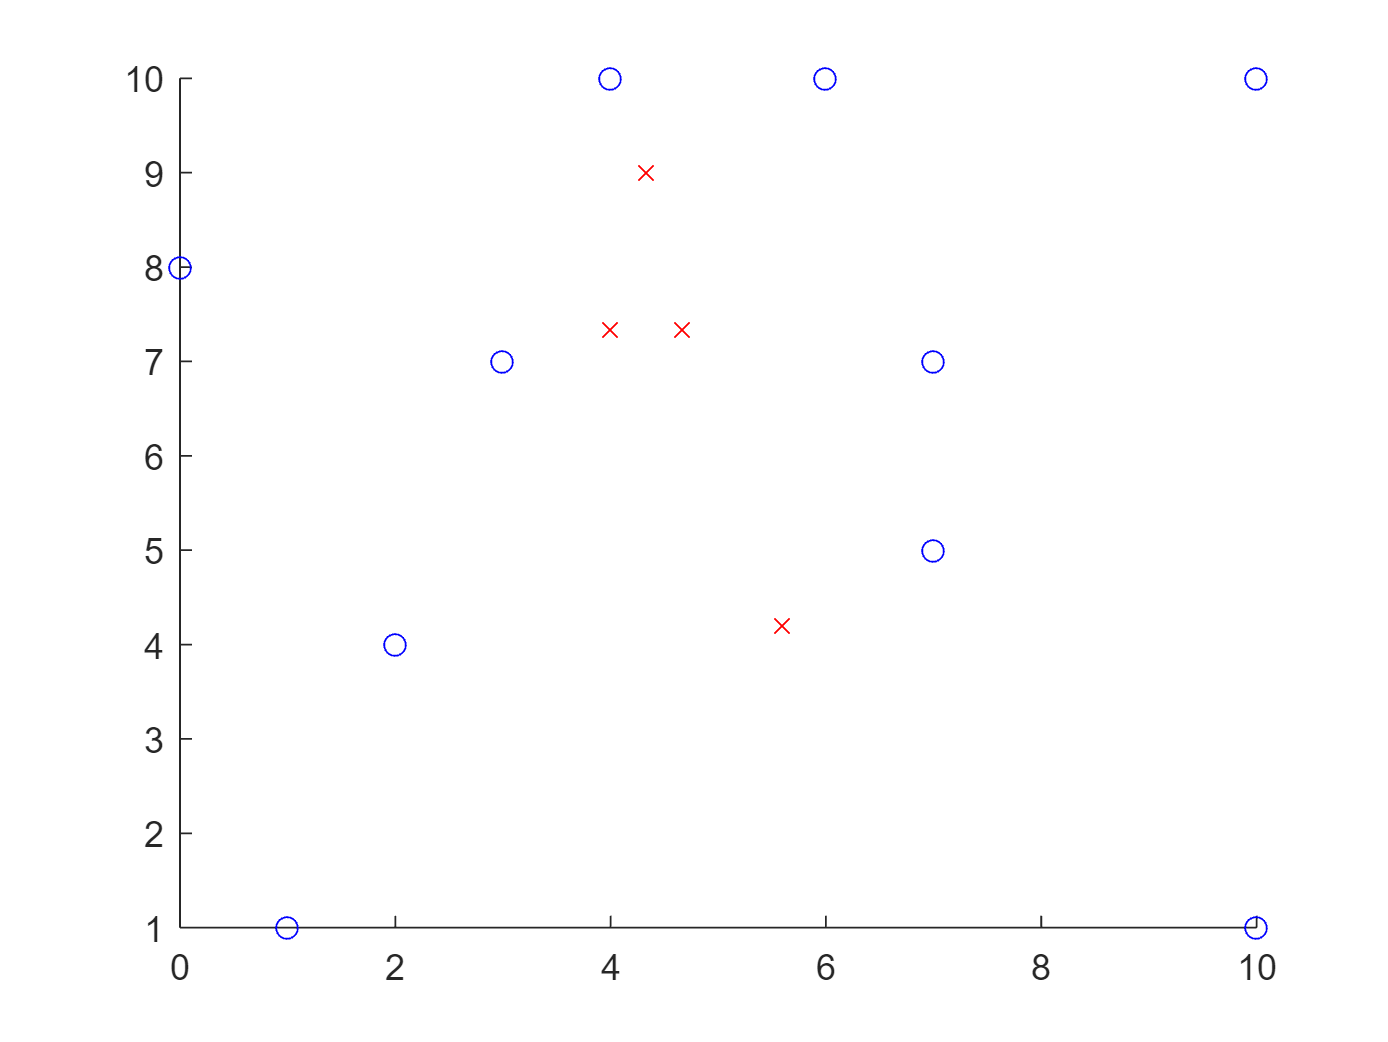

% end of getting all the centroids we need to start
scatter(startCentroids(:,1),startCentroids(:,2),'r','x') % plotting initial centroid
hold off

eplison = 0.001; % defining eplison value
Dp = 100000000; % initializing previous distortion as a large number
while (1)
    values = disteu(randomPoints,(startCentroids)') % getting distances
    [rows,cols] = size(values); % used to determine size for groups matrix
    groups = zeros(rows,cols); % defining groups matrix (frames,numC)
    % for loop for grouping
    for i = 1:rows
        holder = min(values(i,:));
        for j = 1:cols
            if values(i,j) == holder
                groups(i,j) = holder;
            end
        end
    end
    % end of for loop for grouping
    groups % displaying groups; some centroids may not have any points
    Do = zeros(1,cols); % making distortion matrix (1,numCentroids)
    % for loop for summing minimum distances
    for i = 1:cols
        Do(1,i) = (1/10)*sum(groups(:,i)); % summing each column at a time; 1/(frames)
    end
    % end of for loop for summing minimum distances
    Do = sum(Do) % summing final rows of each group; this makes Do one value
    stuff = (Dp - Do)/(Do); % distortion comparison equation
    % if else to decide if another loop needs to be done
    if stuff < eplison
        break;
    else
        Dp = Do;
    end
    % end of if else to decide if another loop needs to be done
    % if another loop needs to be done recalculate centroids
    [r,c] = size(groups); % used for loops below
    holderC = zeros(1,2); % (1,dimensions)
    for i = 1:c
        for j = 1:r
            if groups(j,i) == 0 % in case the centroid is on a point
                % checking to see if centroid is on a point
                hatethis = randomXY(j,:);
                if startCentroids(i,:) == hatethis % only entered if centroid is on data point
                    holderC = [holderC; hatethis];
                end
            else % this if statement gets the original data values
                hatethis = randomXY(j,:);
                holderC = [holderC; hatethis];
            end
        end
        holderC = holderC(2:end,:) % getting rid of the initial 0 0 when holderC was defined
        if isempty(holderC) % just in case a centroid has no data points then do not update the centroid
            startCentroids(i,:) = startCentroids(i,:); % keeps previous centroid the same
        else
            [lastr,lastc] = size(holderC);
            newC = zeros(1,lastc); % (1,dimensions)
            for k = 1:lastc % calculates new centroids; works by doing each column so X then Y then etc
                newC(1,k) = sum(holderC(:,k))/lastr; % sum / number of points in that group
            end
            startCentroids(i,:) = newC; % storing new centroid in place of old one
        end
    end
    startCentroids % seeing new centroid values
    % end of recalculating centroids for next loop
end

values =     6.5659    5.7542    5.9628    7.2801
    4.0552    4.4472    4.7140    6.7676
    3.8873    5.5176    4.2687    3.6056
    3.3333    1.9437    2.9814    5.8138
    2.6667    1.0541    2.7487    6.0166
    1.0541    2.4037    1.6997    3.8210
    3.8006    4.8074    3.2998    1.6125
    3.0185    3.3333    2.3570    3.1305
    7.0079    8.6667    7.3182    5.6036
    8.7242    9.8036    8.2798    5.4406


groups =          0    5.7542         0         0
    4.0552         0         0         0
         0         0         0    3.6056
         0    1.9437         0         0
         0    1.0541         0         0
    1.0541         0         0         0
         0         0         0    1.6125
         0         0    2.3570         0
         0         0         0    5.6036
         0         0         0    5.4406


Do = 3.2480

holderC =      0     8
     3     7


holderC =      3     7
    10    10
     6    10
     4    10


holderC =     10    10
     6    10
     4    10
     7     7


holderC =      6    10
     4    10
     7     7
     2     4
     7     5
     1     1
    10     1


startCentroids =     1.5000    7.5000
    5.7500    9.2500
    6.7500    9.2500
    5.2857    5.4286


values =     8.8600    4.3157    3.3354    6.5668
    1.5811    5.8843    6.8648    5.8780
    3.5355    6.4517    7.0799    3.5828
    5.1478    0.7906    1.0607    4.6269
    3.5355    1.9039    2.8504    4.7488
    1.5811    3.5532    4.3732    2.7738
    6.0415    4.4300    4.2573    1.7670
    5.5227    2.5739    2.2638    2.3255
    6.5192    9.5197   10.0561    6.1628
   10.7005    9.2804    8.8671    6.4681


groups =          0         0    3.3354         0
    1.5811         0         0         0
    3.5355         0         0         0
         0    0.7906         0         0
         0    1.9039         0         0
    1.5811         0         0         0
         0         0         0    1.7670
         0         0    2.2638         0
         0         0         0    6.1628
         0         0         0    6.4681


Do = 2.9390

holderC =      0     8
     2     4
     3     7


holderC =      2     4
     3     7
     6    10
     4    10


holderC =      3     7
     6    10
     4    10
    10    10
     7     7


holderC =      6    10
     4    10
    10    10
     7     7
     7     5
     1     1
    10     1


startCentroids =     1.6667    6.3333
    3.7500    7.7500
    6.0000    8.8000
    6.4286    6.2857


values =     9.1043    6.6427    4.1761    5.1528
    2.3570    3.7583    6.0531    6.6532
    2.3570    4.1382    6.2482    4.9836
    5.6765    3.1820    1.2000    3.7389
    4.3461    2.2638    2.3324    4.4378
    1.4907    1.0607    3.4986    3.5022
    5.4975    4.2573    3.9294    1.4070
    5.3748    3.3354    2.0591    0.9147
    5.3748    7.2887    9.2650    7.5768
    9.8939    9.1992    8.7658    6.3792


groups =          0         0    4.1761         0
    2.3570         0         0         0
    2.3570         0         0         0
         0         0    1.2000         0
         0    2.2638         0         0
         0    1.0607         0         0
         0         0         0    1.4070
         0         0         0    0.9147
    5.3748         0         0         0
         0         0         0    6.3792


Do = 2.7490

holderC =      0     8
     2     4
     1     1


holderC =      2     4
     1     1
     4    10
     3     7


holderC =      1     1
     4    10
     3     7
    10    10
     6    10


holderC =      4    10
     3     7
    10    10
     6    10
     7     5
     7     7
    10     1


startCentroids =     1.0000    4.3333
    2.5000    5.5000
    4.8000    7.6000
    6.7143    7.1429


values =    10.6354    8.7464    5.7271    4.3542
    3.8006    3.5355    4.8166    6.7688
    1.0541    1.5811    4.5607    5.6659
    7.5572    5.7009    2.6833    2.9451
    6.4118    4.7434    2.5298    3.9409
    3.3333    1.5811    1.8974    3.7170
    6.0369    4.5277    3.4059    2.1618
    6.5659    4.7434    2.2804    0.3194
    3.3333    4.7434    7.6158    8.3897
    9.5975    8.7464    8.4024    6.9664


groups =          0         0         0    4.3542
         0    3.5355         0         0
    1.0541         0         0         0
         0         0    2.6833         0
         0         0    2.5298         0
         0    1.5811         0         0
         0         0         0    2.1618
         0         0         0    0.3194
    3.3333         0         0         0
         0         0         0    6.9664


Do = 2.8519

startCentroids % to see values of final centroids

startCentroids =     1.0000    4.3333
    2.5000    5.5000
    4.8000    7.6000
    6.7143    7.1429


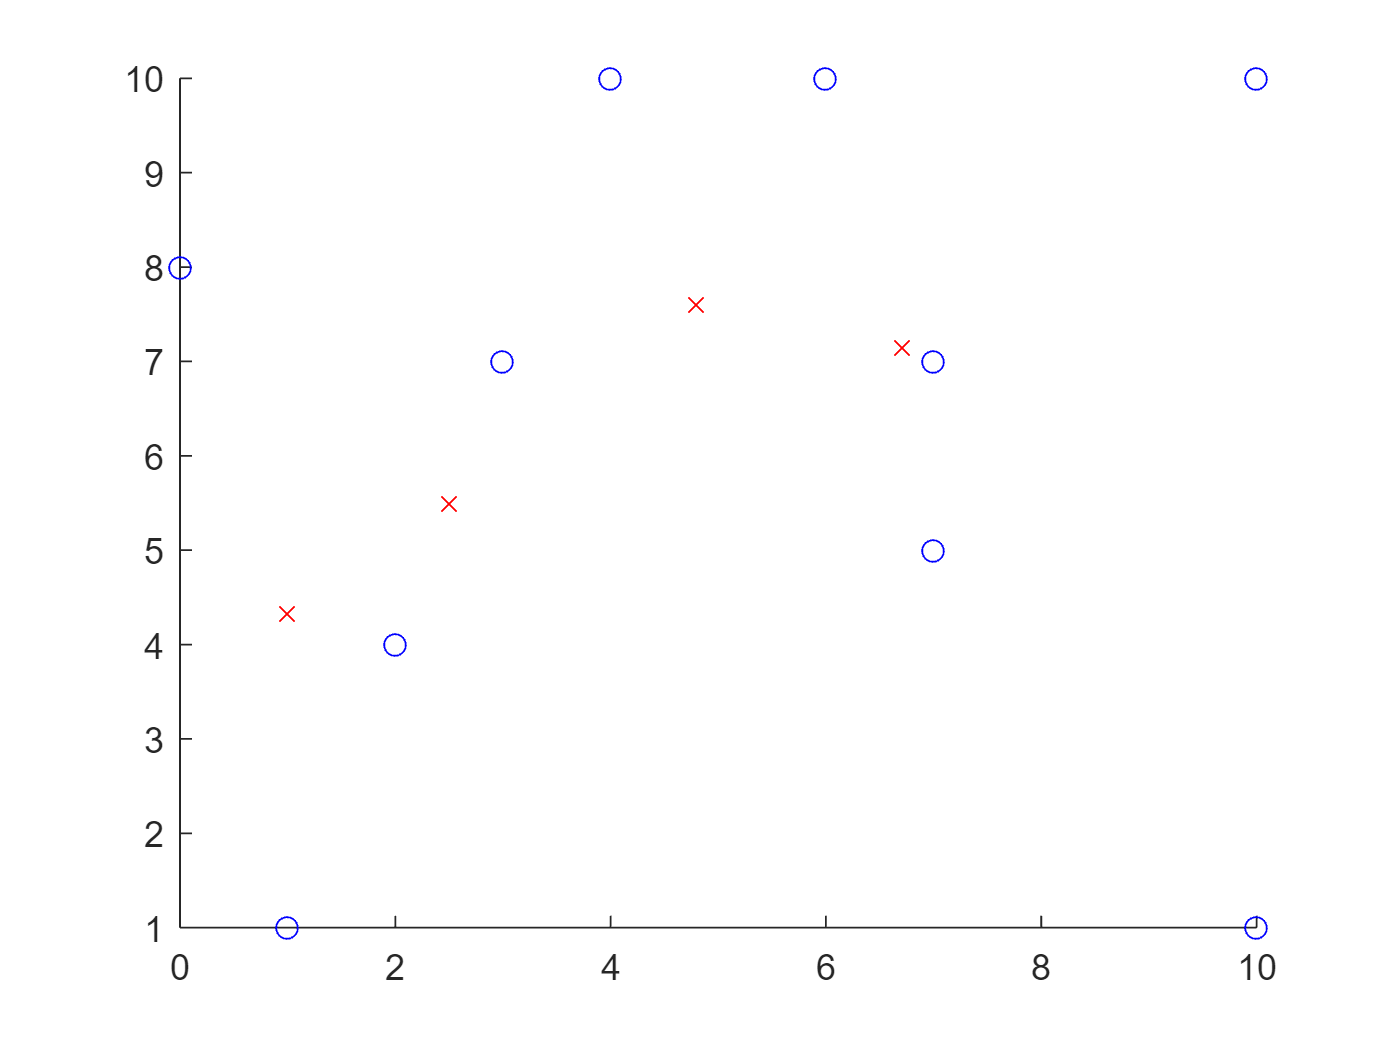

% plotting output; this is to show our algorithm works in 2D
scatter(randomPoints(1,:),randomPoints(2,:),'b','o')
hold on
scatter(startCentroids(:,1),startCentroids(:,2),'r','x')
hold off